% Definicja macierzy
A = [0 2*pi; -2*pi 0];
B = [1; 0];
C = [0 1];
D = 0;

% Jordan form of A
[P, J] = jordan(A);

% Stała e w MATLABie
e = exp(1);

% Krok czasowy
h = 0.8;

% Zdefiniowanie zmiennej symbolicznej t
syms t;

% Definicja A_plus jako funkcji anonimowej
A_plus =@(h) P * expm(J * h) / P;

% Wyrażenie symboliczne dla e^(A*t)
expr = expm(A * t);

% Całkowanie wyrażenia symbolicznego od 0 do h
B_plus = int(expm(A * t) * B, t, 0, h);

% Obliczenie wartości całki dla t = h
B_plus_x = double(subs(B_plus, t, h));

% Wyjściowe wartości C_plus i D_plus
C_plus = C;
D_plus = 0;


% Wyświetlenie wyniku
disp('B_plus_x:');

B_plus_x:


disp(B_plus_x);

   -0.1514
   -0.1100



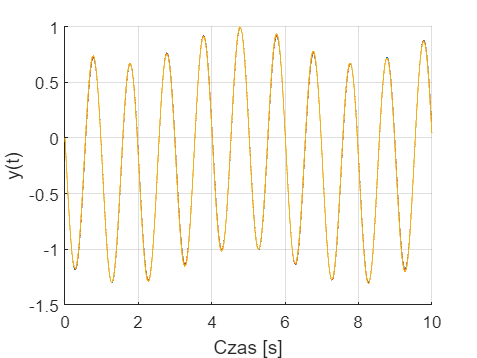

h_tab = [0.1 0.15 0.3];
figure(); hold on;
for i = 1 : 3
    h = h_tab(i);
    % Definicja A_plus jako funkcji anonimowej
    A_plus =@(h) P * expm(J * h) / P;
    
    % Wyrażenie symboliczne dla e^(A*t)
    expr = expm(A * t);
    
    % Całkowanie wyrażenia symbolicznego od 0 do h
    B_plus = int(expm(A * t) * B, t, 0, h);
    
    % Obliczenie wartości całki dla t = h
    B_plus_x = double(subs(B_plus, t, h));
    
    % Wyjściowe wartości C_plus i D_plus
    C_plus = C;
    D_plus = 0;

    sim('DyskM.slx', 10);
    
    y_disc = disc.signals.values;
    y_eks = eks.signals.values;
    time = eks.time;
    
    plot(time, y_eks);

end
xlabel("Czas [s]"); ylabel("y(t)"); hold off; grid on;

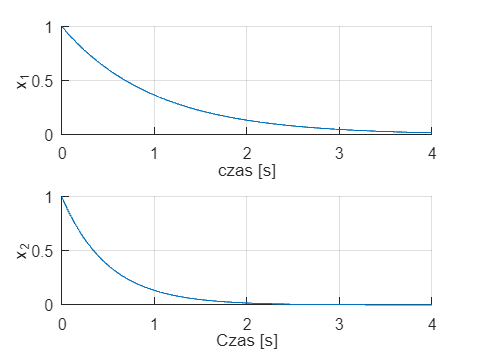

%analityczne
close all;
figure(5)
h=0.01;
ii=0:0.01:4;
jj=0:0.01:4;
x1 = zeros(1,61);
x2 = zeros(1,61);
x10 = 1;
x20 = 1;
j = 1;

for i=ii
    x1(j) = exp(-i)*x10;
    x2(j) = exp(-2*i)*x20;
    j = j+1;
end

subplot(2,1,1);
hold on;
grid on;
plot(ii,x1);
axis([0 4 0 1]);
xlabel('czas [s]');
ylabel('x_1');

subplot(2,1,2);
hold on;
grid on;
plot(ii,x2);
axis([0 4 0 1]);
xlabel('Czas [s]');
ylabel('x_2');

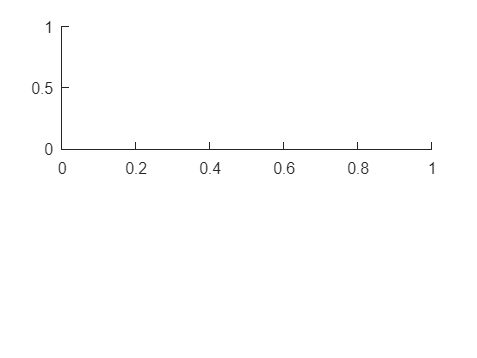

close all;
subplot(2,1,1)

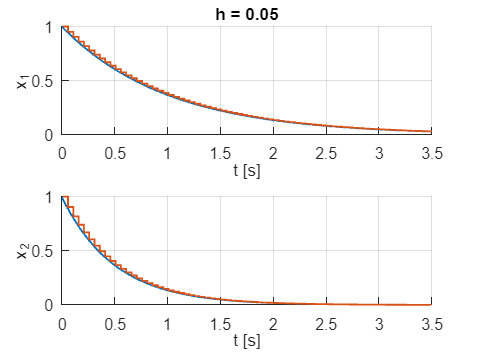

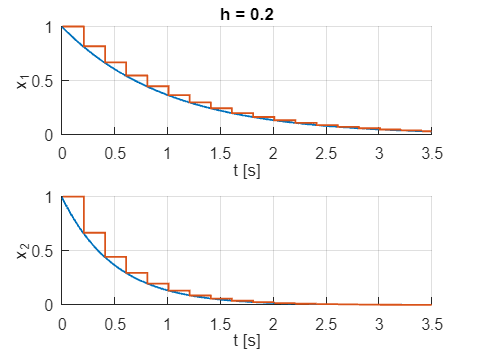

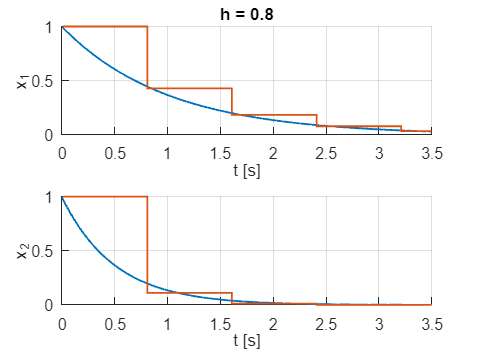

v = [0.05, 0.2, 0.8];
A = [-1, 0; 0, -2];
for h = v
    figure;
    subplot(2,1,1);
    hold on;
    grid on;
    title("h = "+string(h))
    plot(ii,x1, "LineWidth", 1);
    axis([0 4 0 1]);
    xlabel('t [s]');
    ylabel('x_1');
    
    
    I = eye(2);
    X = zeros(2,1);
    X(:,1) = [1;1];
    grid;
    j = 1:100*h:(round(1000/h)+1);
    X = zeros(2,1);
    X(:,1) = [1;1];
    for i = 1:1:(length(j)-1)
        %X(:,i+1)= (I+h*A)*X(:,i);
        %X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
        X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
    end
    grid
    stairs(j./100,X(1,:),'LineWidth', 1);
    xlabel('t [s]');
    ylabel('x_1');
    axis([0 3.5 0 1]);
    %%%
    subplot(2,1,2);
    hold on;
    grid;
    plot(ii,x2, "LineWidth", 1);
    axis([0 4 0 1]);
    xlabel('t [s]');
    ylabel('x_2');
    A = [-1, 0; 0, -2];
    I = eye(2);
    X = zeros(2,1);
    X(:,1) = [1;1];
    v = [0.01, 0.05, 0.15, 0.5];
    j = 1:100*h:(round(1000/h)+1);
    X = zeros(2,1);
    X(:,1) = [1;1];
    for i = 1:1:(length(j)-1)
        %X(:,i+1)= (I+h*A)*X(:,i);
        %X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
        X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
    end
    stairs(j./100,X(2,:),'LineWidth', 1);
    xlabel('t [s]');
    ylabel('x_2');
    
    axis([0 3.5 0 1]);
end

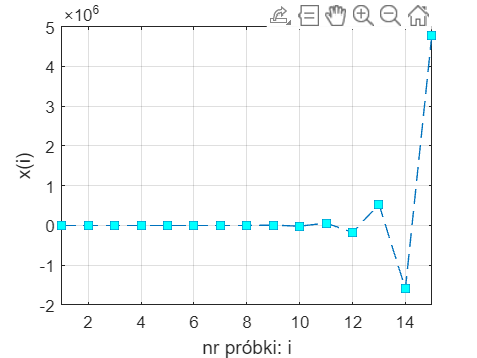

%l < -1
%%% Zadanie 7.3
close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;


h = -3;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x, "--sq", "MarkerFaceColor", "c");
x=zeros(1,15);
x(1)=1;
axis auto; xlim([1 15]);
xlabel('nr próbki: i');
ylabel('x(i)'); grid on;

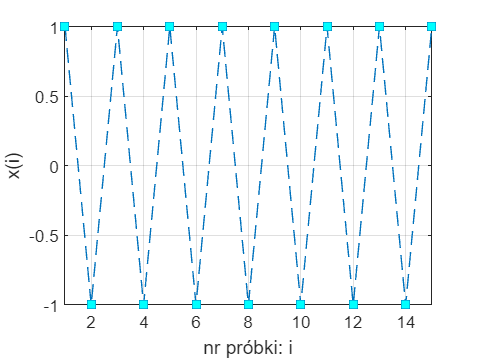

%l =-1
close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = -1;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x, "--sq", "MarkerFaceColor", "c");
x=zeros(1,15);
x(1)=1;
 xlim([1 15]);
xlabel('nr próbki: i');
ylabel('x(i)');
grid on;

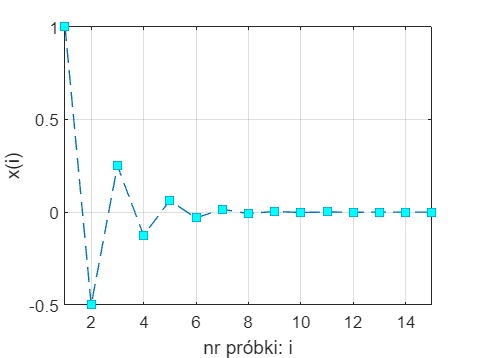

%l in -1 0
close all;
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = -0.5;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x, "--sq", "MarkerFaceColor", "c");
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('nr próbki: i');
ylabel('x(i)');  xlim([1 15]);
grid on;

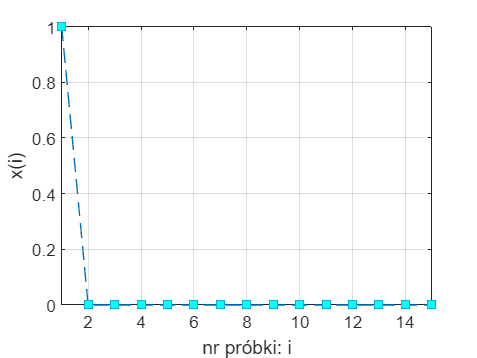

%l = 0
close all;
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = 0;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x, "--sq", "MarkerFaceColor", "c");
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('nr próbki: i');
ylabel('x(i)'); xlim([1 15]);
grid on;

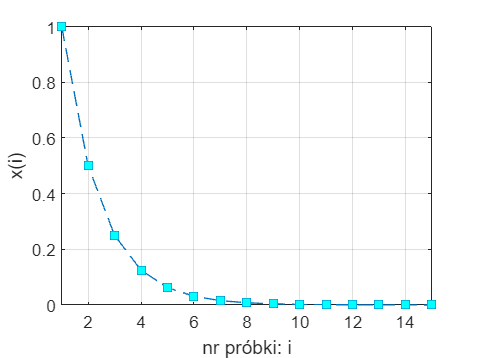

close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = 0.5;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x, "--sq", "MarkerFaceColor", "c");
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('nr próbki: i');
ylabel('x(i)'); xlim([1 15]);
grid on;

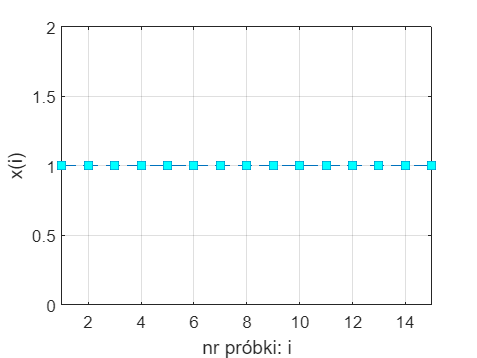

close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = 1;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x, "--sq", "MarkerFaceColor", "c");
x=zeros(1,15);
x(1)=1;
axis auto;
xlabel('nr próbki: i');
ylabel('x(i)'); xlim([1 15]);
grid on;

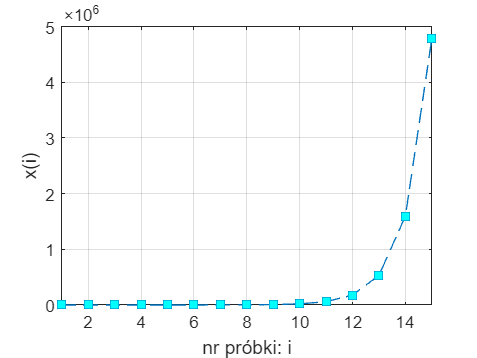

close all;
x=zeros(1,15);
x(1)=1;
ii=1:1:14;
jj=1:1:15;

h = 3;
for i=ii
    x(i+1)=h*x(i);
end
h_minus_11=plot(jj,x, "--sq", "MarkerFaceColor", "c");
x=zeros(1,15);
x(1)=1;
axis auto;
xlim([1 15])
xlabel('nr próbki: i');
ylabel('x(i)'); xlim([1 15]);
grid on;

%rekurencyjna
% Definiowanie liczby iteracji
n = 50; % liczba wartości do wygenerowania

% Inicjalizacja wektora wynikowego
x = zeros(1, n);

% Ustawienie wartości początkowych
x(1) = 0;
x(2) = 1;

% Pomiar czasu obliczeń
tic;
% Obliczanie kolejnych wartości według wzoru iteracyjnego
for i = 3:n
    x(i) = x(i-1) + x(i-2);
end
elapsed_time_iterative = toc;
wynik = zeros(1,n);
for i = 1:n-1
    wynik(i) = 1 + (x(i)/x(i+1));
end
wynik(end-1)

ans = 1.6180

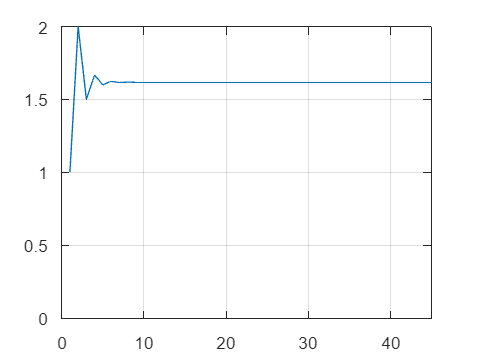

figure();
plot(wynik); grid on; axis([0 45 0 2])

% Wyświetlanie wyników
disp('Wyniki metody iteracyjnej:');

Wyniki metody iteracyjnej:


disp(x(end));

   7.7787e+09



disp(['Czas obliczeń metody iteracyjnej: ', num2str(elapsed_time_iterative), ' sekund']);

Czas obliczeń metody iteracyjnej: 0.0033363 sekund


%wzór
% Definiowanie liczby iteracji
n = 1000; % liczba wartości do wygenerowania

% Inicjalizacja wektora wynikowego
x = zeros(1, n);

% Pomiar czasu obliczeń
tic;
% Obliczanie wartości według wzoru zamkniętego
for i = 0:n-1
    x(i+1) = (1/sqrt(5)) * (((1 + sqrt(5))/2)^i - ((1 - sqrt(5))/2)^i);
end
elapsed_time_closed_form = toc;

% Wyświetlanie wyników
disp('Wyniki metody zamkniętej postaci:');

Wyniki metody zamkniętej postaci:


disp(x(end));

  2.6864e+208



disp(['Czas obliczeń metody zamkniętej postaci: ', num2str(elapsed_time_closed_form), ' sekund']);

Czas obliczeń metody zamkniętej postaci: 0.0075035 sekund


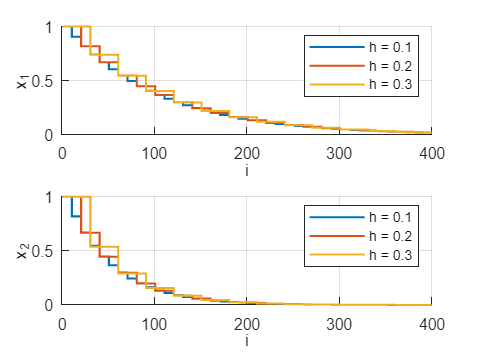

close all;
subplot(2,1,1)
A = [-1, 0; 0, -2];
I = eye(2);
X = zeros(2,1);
X(:,1) = [1;1];
figure(1);
hold on
grid
v = [0.1, 0.2, 0.3];
for h = v
j = 1:100*h:(round(1000/h)+1);
X = zeros(2,1);
X(:,1) = [1;1];
for i = 1:1:(length(j)-1)
%X(:,i+1)= (I+h*A)*X(:,i);
% X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
end
stairs(j,X(1,:),'LineWidth', 1.1);
end
xlabel('i');
ylabel('x_1');
legend('h = 0.1','h = 0.2','h = 0.3');
axis([0 400 0 1]);
%%%
subplot(2,1,2)
A = [-1, 0; 0, -2];
I = eye(2);
X = zeros(2,1);
X(:,1) = [1;1];
figure(1);
hold on
grid
v = [0.1, 0.2, 0.3];
for h = v
j = 1:100*h:(round(1000/h)+1);
X = zeros(2,1);
X(:,1) = [1;1];
for i = 1:1:(length(j)-1)
%X(:,i+1)= (I+h*A)*X(:,i);
% X(:,i+1)= ((I-h*A)^(-1))*X(:,i);
X(:,i+1)= ((I-0.5*h*A)^(-1))*((I+0.5*h*A)*X(:,i));
end
stairs(j,X(2,:),'LineWidth', 1.1);
end
xlabel('i');
ylabel('x_2');
legend('h = 0.1','h = 0.2','h = 0.3');
axis([0 400 0 1]);
saveas(gcf,'8.png')